% calculate and plot state value

Animal = 's19';
Date = '20200928';
totalTrial = 150;
Key = 'heavy90';
gamma = 0.9; % discount factor
% force_thres = 0.1; % remove trial which has more than force_thres at the beggining of the trial
working_directory = 'C:\Users\NAOHIRO-YAMAUCHI\OneDrive - OIST\OIST_rotation\Doya_rotation\Makino2022\Makino2022NatureNeuroscience';
% resistance_table = readtable(['D:\Doya_rotation\20200928_s19_heavy90' filesep 'resistance.csv']);%,'NumHeaderLines',1);
% behavior_table = readtable(['D:\Doya_rotation\20200928_s19_heavy90' filesep 'behavior.csv']); %,'NumHeaderLines',1);
data_folder = ['D:\Doya_rotation' filesep Date '_' Animal '_' Key];
load ([data_folder filesep Animal '_behavior_' Date '_' Key '.mat'])
behavior_data = behavior_neural_time_convolved_zscored;

neural_activity_table = readtable(['D:\Doya_rotation' filesep Date '_' Animal '_' Key filesep 'cell traces.csv']);%,'NumHeaderLines',1);
neural_activity_data = table2array(neural_activity_table(:,2:size(neural_activity_table,2)));

neural_activity_data

neural_activity_data = 1.0e+04 *

   -0.0105   -0.0084    0.1286    0.0054   -0.0211    0.0094    0.0044   -0.0351    0.0143   -0.0131   -0.0183   -0.0107   -0.0217   -0.0009   -0.0004    0.0276   -0.0261   -0.0498    0.0669    0.0118   -0.0214   -0.0317    0.0313   -0.0269    0.0096   -0.0318    0.0145    0.0111   -0.0425    0.0190   -0.0114   -0.0298    0.0531   -0.0337   -0.0526    0.0072    0.0079    0.0177    0.0456    0.0239   -0.0054    0.0160    0.0149    0.0160    0.0590    0.0014   -0.0111   -0.0364    0.0533   -0.0509
   -0.0059   -0.0148    0.1229    0.0036   -0.0190    0.0051    0.0089   -0.0244    0.0144   -0.0129    0.0088   -0.0159   -0.0107    0.0039    0.0008    0.0326   -0.0206   -0.0135    0.0612    0.0011   -0.0169   -0.0284    0.0077   -0.0192    0.0068   -0.0361    0.0091    0.0092   -0.0468    0.0402   -0.0066   -0.0142    0.0642   -0.0425   -0.0513   -0.0078    0.0009    0.0196    0.0393    0.0141    0.0059    0.0191    0.0162    0.0227    0.0556   -0.0023   -0

% temporal processing of neural activity data
% have to change for real data
processed_neural_activity_data = max((neural_activity_data + repmat(std(neural_activity_data),length(neural_activity_data),1))./repmat(std(neural_activity_data),length(neural_activity_data),1),zeros(size(neural_activity_data)))

processed_neural_activity_data =     0.7900    0.8729    2.4340    1.1187    0.7233    1.2194    1.0942    0.0475    1.2493    0.7547    0.7600    0.8270    0.5007    0.9835    0.9914    1.6777    0.6966    0.0371    2.1602    1.2499    0.5539    0.4139    1.3340    0.6110    1.1123    0.3445    1.2401    1.2913         0    1.5833    0.8460    0.4609    2.0782    0.4785    0.4501    1.1393    1.1812    1.5303    2.5605    1.5138    0.8818    1.2597    1.3791    1.4024    1.7425    1.0256    0.7810    0.2780    2.2201         0
    0.8819    0.7762    2.3710    1.0777    0.7502    1.1179    1.1920    0.3368    1.2508    0.7580    1.1159    0.7426    0.7530    1.0724    1.0179    1.8004    0.7604    0.7383    2.0603    1.0233    0.6480    0.4761    1.0818    0.7227    1.0798    0.2558    1.1510    1.2406         0    2.2374    0.9103    0.7430    2.3030    0.3412    0.4630    0.8486    1.0202    1.5877    2.3463    1.3038    1.1302    1.3096    1.4142    1.5718    1.7006    0.9565    0.

behavior_data

behavior_data =    -0.1219   -0.1871   -0.2209   -0.2058   -0.2058   -0.1988   -0.2063   -0.2063   -0.2062   -0.2062   -0.7860   -0.5563   -0.6702   -0.6533   -0.6531   -0.1649   -0.1649   -0.1649   -0.1648   -0.1648   -0.4526   -0.5275   -0.1969    0.3339   -0.9404   -0.9401   -0.0928   -0.1550    0.5330   -0.4307   -0.2696   -0.3589   -0.3374   -0.3186   -0.3186   -0.3185   -0.3184   -0.3184
   -0.0547   -0.2041   -0.2217   -0.2058   -0.2058   -0.1999   -0.2063   -0.2063   -0.2062   -0.2062   -0.6422   -0.5546   -0.6861   -0.6533   -0.6531   -0.1649   -0.1649   -0.1649   -0.1648   -0.1648   -0.4526   -0.5275   -0.1969    0.3339   -0.9404   -0.9401   -0.0992   -0.2073    0.5893   -0.4314   -0.2496   -0.4064   -0.3279   -0.3111   -0.3186   -0.3185   -0.3184   -0.3184
    0.0139   -0.2253   -0.2191   -0.2058   -0.2058   -0.2028   -0.2063   -0.2063   -0.2062   -0.2062   -0.4288   -0.5740   -0.6993   -0.6533   -0.6531   -0.1649   -0.1649   -0.1649   -0.1648   -0.1648   -0.4526   -0.5275  

% GLM: predict neural activity from convolved task variables
GLM = cell(size(neural_activity_data,2),2);

mincoefs = cell(size(neural_activity_data,2),2);
for i_cell = 1:size(neural_activity_data,2)
    [GLM{i_cell,1}, GLM{i_cell,2}] = lassoglm(behavior_data,processed_neural_activity_data(:,i_cell),'poisson','Alpha',0.9,'CV',5,'NumLambda',100);
    idxLambdaMinDeviance = GLM{i_cell,2}.IndexMinDeviance;
    mincoefs{i_cell,1} = find(GLM{i_cell,1}(:,idxLambdaMinDeviance));
    idxLambda1SE = GLM{i_cell,2}.Index1SE;
    mincoefs{i_cell,2} = find(GLM{i_cell,1}(:,idxLambda1SE));
end

% [GLM{1,1}, GLM{1,2}] = lassoglm(behavior_data,processed_neural_activity_data(:,1),'poisson','Alpha',0.9,'CV',5,'NumLambda',100);

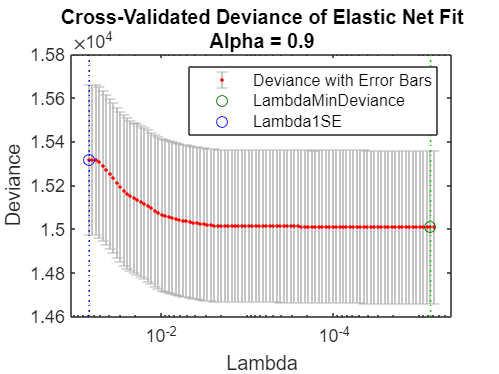

% lassoPlot(GLM{1,1},GLM{1,2},'plottype','CV'); 
% legend('show') % Show legend

% idxLambdaMinDeviance = GLM{1,2}.IndexMinDeviance;
% mincoefs = find(GLM{1,1}(:,idxLambdaMinDeviance))

mincoefs =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


% idxLambda1SE = GLM{1,2}.Index1SE;
% min1coefs = find(GLM{1,1}(:,idxLambda1SE))


min1coefs =

  0×1 empty double column vector



 % trial_start_conv, trial_end_conv, resistance_high_conv, resistance_low_conv, position_conv, force_conv, reward_conv
 % 1-5,6-10,11-15,16-20,21-26,27-31,32-38
 trial_cell = zeros(size(neural_activity_data,2),1);
 resistance_cell = zeros(size(neural_activity_data,2),1);
 position_cell = zeros(size(neural_activity_data,2),1);
 force_cell = zeros(size(neural_activity_data,2),1);
 reward_cell = zeros(size(neural_activity_data,2),1);
 for i_cell = 1:size(neural_activity_data,2)
    if sum(mincoefs{i_cell,2}<11) > 0
        trial_cell(i_cell) = 1;
    end
    if sum(mincoefs{i_cell,2}>10 & mincoefs{i_cell,2}<21) > 0
        resistance_cell(i_cell) = 1;
    end
    if sum(mincoefs{i_cell,2}>20 & mincoefs{i_cell,2}<27) > 0
        position_cell(i_cell) = 1;
    end
    if sum(mincoefs{i_cell,2}>26 & mincoefs{i_cell,2}<32) > 0
        force_cell(i_cell) = 1;
    end
    if sum(mincoefs{i_cell,2}>31) > 0
        reward_cell(i_cell) = 1;
    end
 end
 cell_representations = [trial_cell, resistance_cell, position_cell, force_cell, reward_cell];

neural_traits_table = readtable(['D:\Doya_rotation' filesep Date '_' Animal '_' Key filesep 'cell traces-props.csv']);%,'NumHeaderLines',1);
centroidY = neural_traits_table.('CentroidY')

centroidY =    436
   531
   589
   338
   412
   397
   426
   488
   258
   430


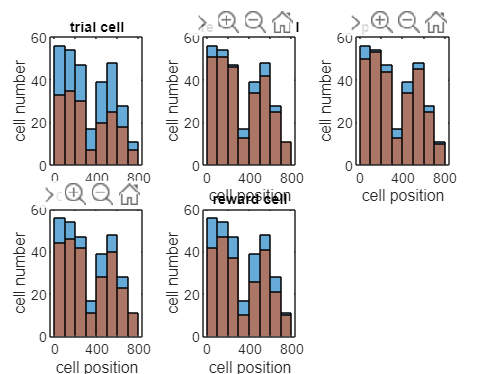

% plot the relation between position and representaion of each variables
addpath(['C:\Users\NAOHIRO-YAMAUCHI\OneDrive - OIST\OIST_rotation\Yoshida_rotation\wide_field_MATLAB\Wide-field-calcium-imaging\PCA_and_ICA\Subaxis']);
titles = {'trial cell', 'resistance cell', 'position cell', 'force cell', 'reward cell'};
for i = 1:5
% state_value_average_reshape = reshape(state_value_average(2,:),[6,2]);
% heatmap(state_value_average_reshape)
    subaxis(2,3,i, 'Spacing', 0.04, 'Padding', 0.04, 'Margin', 0.06);
%     clims = [-3 10]; % use clims specified by the previous cell
%     image = mean(mean_RecICA_Temp(:,time_points(i,1)*fps/1000:time_points(i,2)*fps/1000),2);
%     state_value_average_reshape = reshape(state_value_average(i,:),[6,2]); %mean(mean_RecICA_lift(:,timepoints(i,1):timepoints(i,2)),2);
%     imagesc(state_value_average_reshape,[0 1]);
%     colormap jet;
%     axis square;
%     axis off;
    h1 = histogram(centroidY);
    hold on
    h2 = histogram(centroidY(cell_representations(:,i)==1));
    title(titles(i), 'FontSize',8);
    xlabel('cell position');
    ylabel('cell number');

end

% GLM_230210 = GLM;

% save table as mat file
save(['D:\Doya_rotation' filesep Date '_' Animal '_' Key filesep Animal '_behavior_' Date '_' Key '.mat'], 'GLM'); % 'GLM_230210');

% bin the state and action to calculate state value and action value
behavior_sequence_discretized = cell(1,length(data));
for i_trial = 1:length(data)
    % bin lever position (630-647 -> 6-1)
    position_temp = data{i_trial}(:,3);
    position_discrete = 7 - min(max(floor((position_temp - 623)/4),1),6);
%     position_discrete = 7 - min(max(idivide((position_temp - 623),4,'floor'),1),6);
%     position_discrete = zeros(length(position_temp));
%     for j_time = 1:length(position_temp)
%         if position_temp(j_time) <= 
    % bin applied force (0-0.7 -> 0-7)
    force_temp = data{i_trial}(:,4);
    force_discrete = min(max(floor(force_temp/0.1),0),7);
%     force_discrete = min(max(idivide(force_temp,0.1,'floor'),0),7);
    behavior_sequence_discretized{i_trial} = cat(2,cat(2,data{i_trial},position_discrete),force_discrete);
end

% analyze first 50 of last 50 trials as before and after adaptation
behavior_adapt = cell(2,50);
behavior_adapt(1,:) = behavior_sequence_discretized(1:50); % behavior_before_adapt
behavior_adapt(2,:) = behavior_sequence_discretized(length(data)-49:length(data)); % behavior_after_adapt

% calculate state value for each discretized state
% 2 (resistance) * 6 (position) = 12 states
state_value = cell(2,12);
for k = 1:2
    for i_trial = 1:50
        % resistance for each trial
        if behavior_adapt{k,i_trial}(1,2) == 8
            resistance_trial = 1;
        else 
            resistance_trial = 2;
        end
        % rewarded step (end of trial) or not (0)
        if max(behavior_adapt{k,i_trial}(:,5)) == 1
            rewarded_trial = length(behavior_adapt{k,i_trial});
        else 
            rewarded_trial = 0;
        end
        % add state_value of each step
        for j_step = 1:size(behavior_adapt{k,i_trial},1)
            state_temp = (resistance_trial-1)*6+behavior_adapt{k,i_trial}(j_step,7);
            if rewarded_trial >= 1
                state_value_temp = gamma.^(rewarded_trial-j_step);
            else
                state_value_temp = 0;
            end
            state_value{k,state_temp} = [state_value{k,state_temp} state_value_temp];
        end
    end
end

state_value_average = zeros(2,12);
for i = 1:12
    state_value_average(1,i) = mean(state_value{1,i});
    state_value_average(2,i) = mean(state_value{2,i});
end
% rewarded after how many steps or not

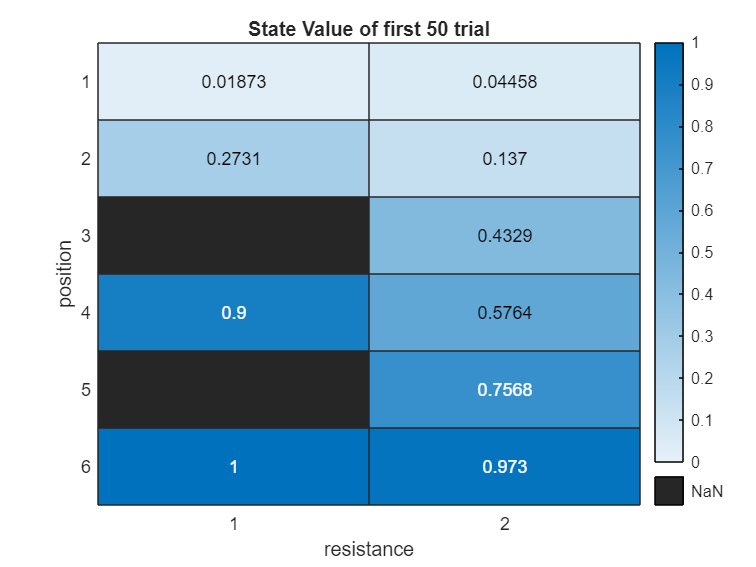

% plot state value
state_value_average_reshape = reshape(state_value_average(1,:),[6,2]);
heatmap(state_value_average_reshape,'ColorLimits',[0 1],'Title','State Value of first 50 trial','XLabel','resistance','YLabel','position')

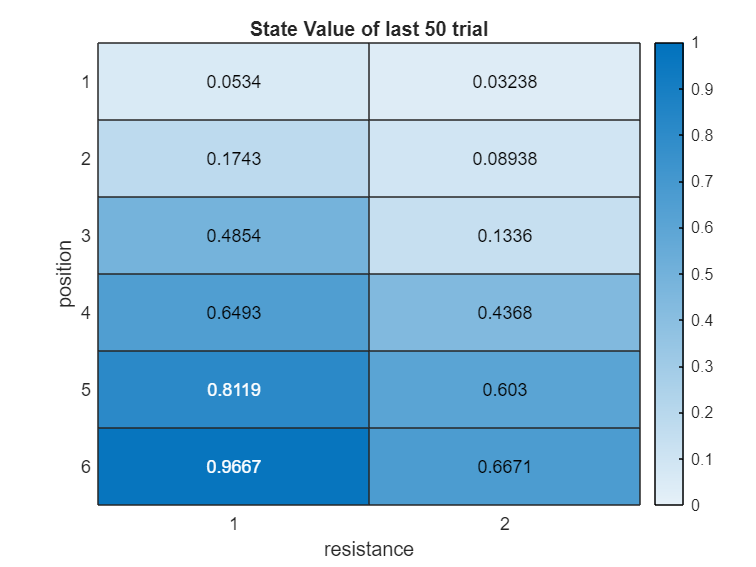

state_value_average_reshape = reshape(state_value_average(2,:),[6,2]);
heatmap(state_value_average_reshape,'ColorLimits',[0 1],'Title','State Value of last 50 trial','XLabel','resistance','YLabel','position')

% analyze by binned 20 trials
num_bins = 5; % 6 % number of bins
behavior_adapt = cell(num_bins,20);
for i = 1:num_bins
%     if i == 6
%         behavior_adapt(6,:) = behavior_sequence_discretized(length(behavior_sequence_processed)-19:length(behavior_sequence_processed));
%     else
        behavior_adapt(i,:) = behavior_sequence_discretized((i-1)*20+1:i*20);
%     end
end
% behavior_adapt(1,:) = behavior_sequence_discretized(1:50); % behavior_before_adapt
% behavior_adapt(2,:) = behavior_sequence_discretized(length(behavior_sequence_processed)-49:length(behavior_sequence_processed)); % behavior_after_adapt

% calculate state value for each discretized state
% 2 (resistance) * 6 (position) = 12 states
state_value = cell(num_bins,12);
for k = 1:num_bins
    for i_trial = 1:20
        % resistance for each trial
        if behavior_adapt{k,i_trial}(1,2) == 8
            resistance_trial = 1;
        else 
            resistance_trial = 2;
        end
        % rewarded step (end of trial) or not (0)
        if max(behavior_adapt{k,i_trial}(:,5)) == 1
            rewarded_trial = length(behavior_adapt{k,i_trial});
        else 
            rewarded_trial = 0;
        end
        % add state_value of each step
        for j_step = 1:size(behavior_adapt{k,i_trial},1)
            state_temp = (resistance_trial-1)*6+behavior_adapt{k,i_trial}(j_step,7);
            if rewarded_trial >= 1
                state_value_temp = gamma.^(rewarded_trial-j_step);
            else
                state_value_temp = 0;
            end
            state_value{k,state_temp} = [state_value{k,state_temp} state_value_temp];
        end
    end
end

state_value_average = zeros(num_bins,12);
for k = 1:num_bins
    for i = 1:12
        state_value_average(k,i) = mean(state_value{k,i});
%     state_value_average(2,i) = mean(state_value{2,i});
    end
end
% rewarded after how many steps or not

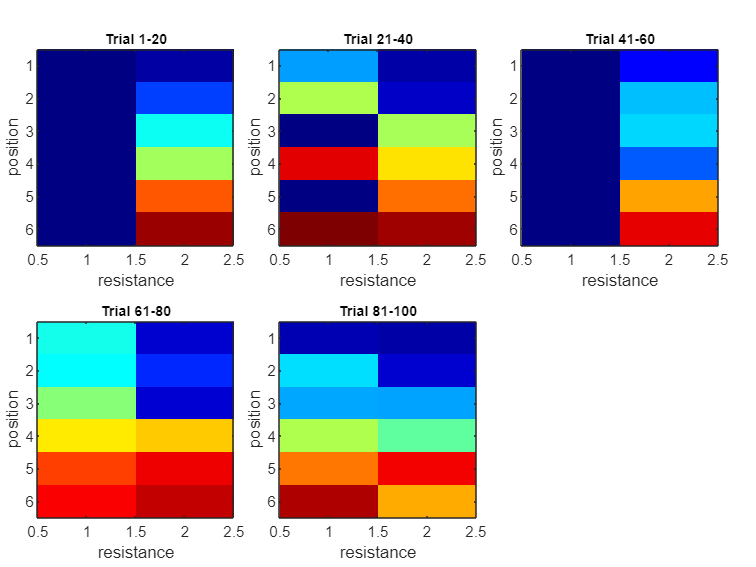

% plot state value
addpath(['C:\Users\NAOHIRO-YAMAUCHI\OneDrive - OIST\OIST_rotation\Yoshida_rotation\wide_field_MATLAB\Wide-field-calcium-imaging\PCA_and_ICA\Subaxis']);
for i = 1:num_bins
% state_value_average_reshape = reshape(state_value_average(2,:),[6,2]);
% heatmap(state_value_average_reshape)
    subaxis(2,3,i, 'Spacing', 0.02, 'Padding', 0.02, 'Margin', 0.03);
%     clims = [-3 10]; % use clims specified by the previous cell
%     image = mean(mean_RecICA_Temp(:,time_points(i,1)*fps/1000:time_points(i,2)*fps/1000),2);
    state_value_average_reshape = reshape(state_value_average(i,:),[6,2]); %mean(mean_RecICA_lift(:,timepoints(i,1):timepoints(i,2)),2);
    imagesc(state_value_average_reshape,[0 1]);
    colormap jet;
    axis square;
%     axis off;
    title(['Trial ' num2str(1+(i-1)*20) '-' num2str(i*20)], 'FontSize',8);
    xlabel('resistance');
    ylabel('position');

end

% analyze by linearly increase the contribution of past trials
effective_trials = 50; % maximam trial which affect current state or action value
% calculate state value for each discretized state
% 2 (resistance) * 6 (position) = 12 states
trial_num = length(data);
state_value = cell(trial_num,12);
for i_trial = 1:trial_num
     % resistance for each trial
    if behavior_sequence_discretized{i_trial}(1,2) == 8
        resistance_trial = 1;
    else 
        resistance_trial = 2;
    end
    % rewarded step (end of trial) or not (0)
    if max(behavior_sequence_discretized{i_trial}(:,5)) == 1
        rewarded_trial = size(behavior_sequence_discretized{i_trial},1);
    else 
        rewarded_trial = 0;
    end
    % calculate state_value of each step
    for j_step = 1:size(behavior_sequence_discretized{i_trial},1)
        state_temp = (resistance_trial-1)*6+behavior_sequence_discretized{i_trial}(j_step,7);
        if rewarded_trial >= 1
            state_value_temp = gamma.^(rewarded_trial-j_step);
        else
            state_value_temp = 0;
        end
        state_value{i_trial,state_temp} = [state_value{i_trial,state_temp} state_value_temp];
    end   
end

state_value_average = zeros(trial_num,12);
for i_trial = 1:trial_num
    for i = 1:12
        state_value_average(i_trial,i) = mean(state_value{i_trial,i});
%     state_value_average(2,i) = mean(state_value{2,i});
    end
end
% rewarded after how many steps or not

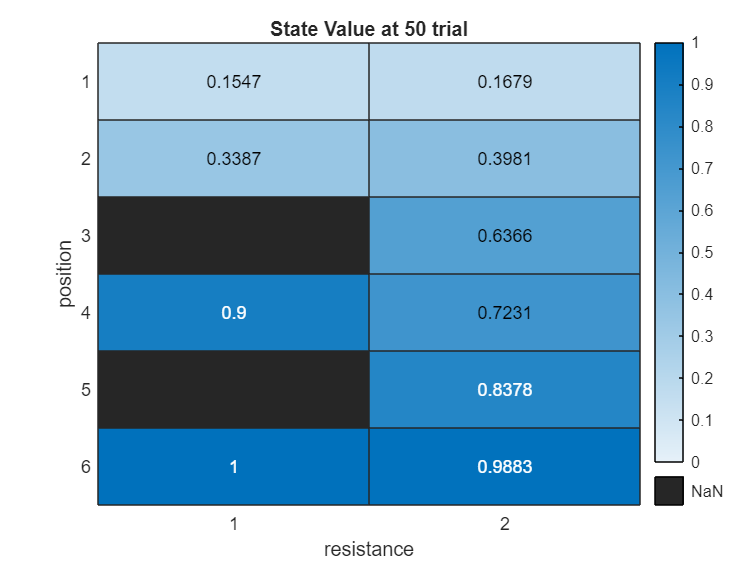

% plot state value at trial50 
clf('reset')
state_value_weighted_average = zeros(1,12);
% for i_trial = 1:effective_trials
%     for i = 1:12
%         state_value_weighted_average(i) = state_value_weighted_average(i) + i_trial*state_value_average(50-effective_trials+i_trial,i);
%     end
% end
for i = 1:12
    sum_weights = 0;
    for i_trial = 1:effective_trials
        if ~isnan(state_value_average(50-effective_trials+i_trial,i))
            state_value_weighted_average(i) = state_value_weighted_average(i) + i_trial*state_value_average(50-effective_trials+i_trial,i);
            sum_weights = sum_weights + i_trial;
        end
    end
    state_value_weighted_average(i) = state_value_weighted_average(i)/sum_weights;
end

% state_value_weighted_average = state_value_weighted_average/((1+effective_trials)*effective_trials/2);

state_value_weighted_average_reshape = reshape(state_value_weighted_average,[6,2]);
heatmap(state_value_weighted_average_reshape,'ColorLimits',[0 1],'Title','State Value at 50 trial','XLabel','resistance','YLabel','position')

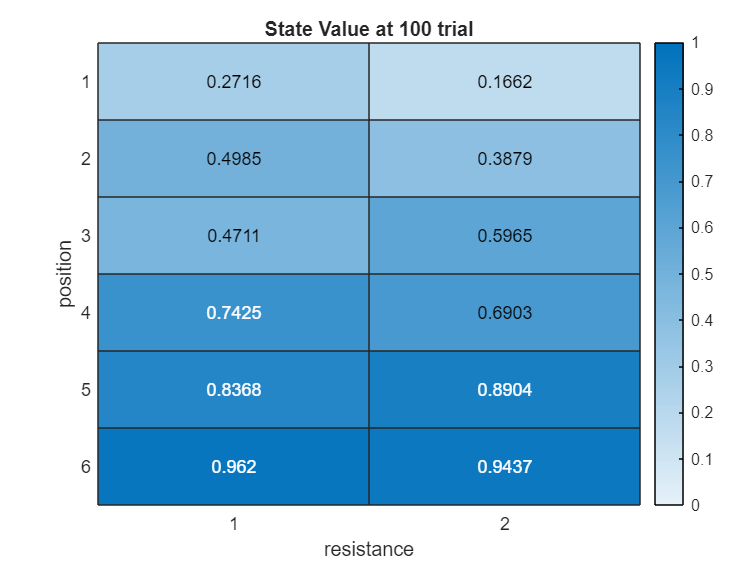

% plot state value at trial100 
% clf('reset')
state_value_weighted_average = zeros(1,12);
% for i_trial = 1:effective_trials
%     for i = 1:12
%         state_value_weighted_average(i) = state_value_weighted_average(i) + i_trial*state_value_average(50-effective_trials+i_trial,i);
%     end
% end
for i = 1:12
    sum_weights = 0;
    for i_trial = 1:effective_trials
        if ~isnan(state_value_average(100-effective_trials+i_trial,i))
            state_value_weighted_average(i) = state_value_weighted_average(i) + i_trial*state_value_average(100-effective_trials+i_trial,i);
            sum_weights = sum_weights + i_trial;
        end
    end
    state_value_weighted_average(i) = state_value_weighted_average(i)/sum_weights;
end

% state_value_weighted_average = state_value_weighted_average/((1+effective_trials)*effective_trials/2);

state_value_weighted_average_reshape = reshape(state_value_weighted_average,[6,2]);
heatmap(state_value_weighted_average_reshape,'ColorLimits',[0 1],'Title','State Value at 100 trial','XLabel','resistance','YLabel','position')

gamma = 0.9 % discount factor

gamma = 0.9000

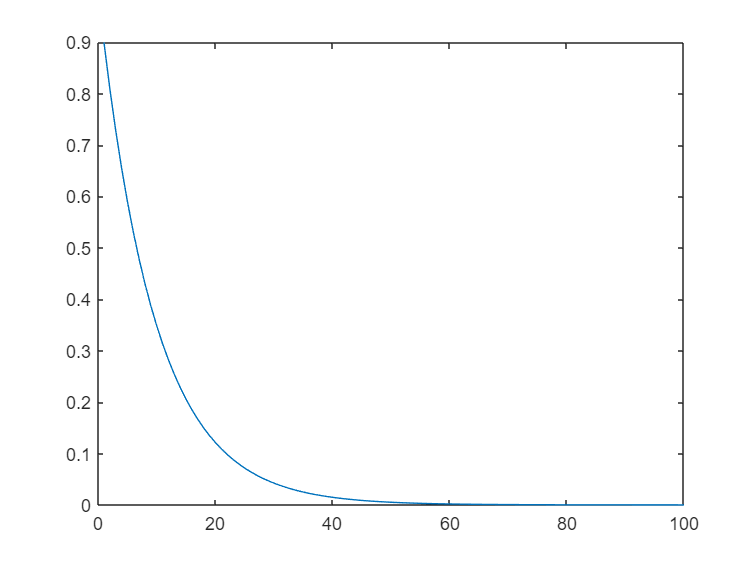

x = 1:100;
y = gamma.^x;
plot(y)

steps = 0;
for i_trial = 1:length(data)
    steps = steps + length(data{i_trial});
end
steps = steps/length(data)

steps = 75.0588

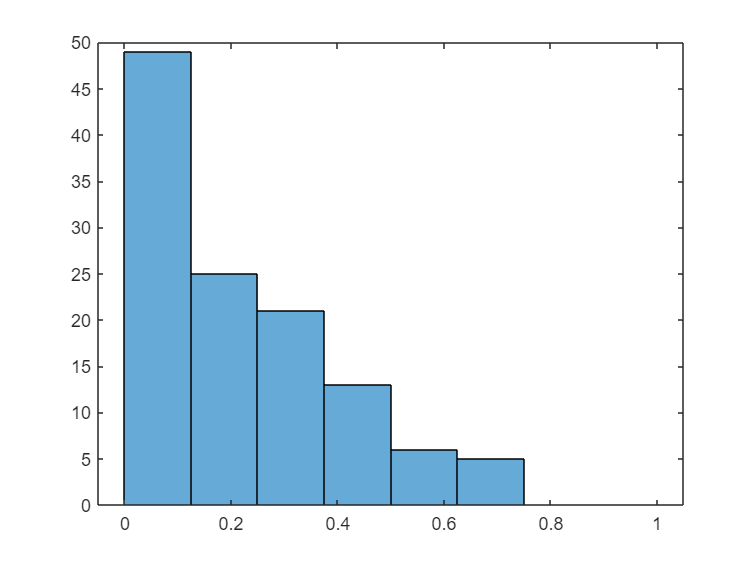

clf('reset')
max_forces = zeros(1,length(data));
for i = 1:length(data)
    max_forces(i) = max(data{i}(:,4));
end
histogram(max_forces, 'BinLimits',[0 1])